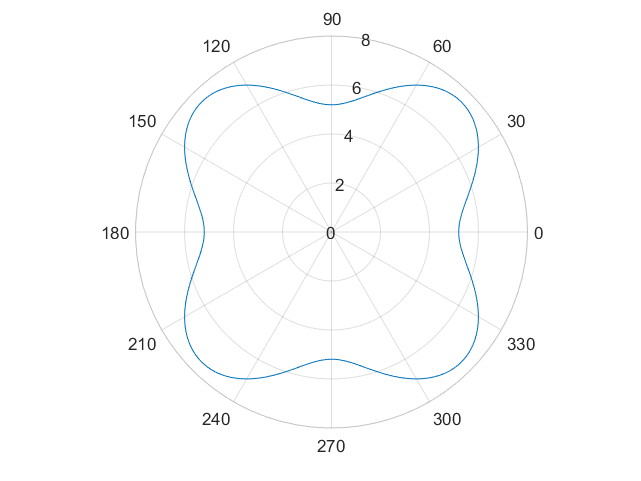

%clover(rotación, escala, resolución)
rot = pi/4;
escala = 1;
puntos = 301;
[x, y] = clover(rot, escala, puntos);

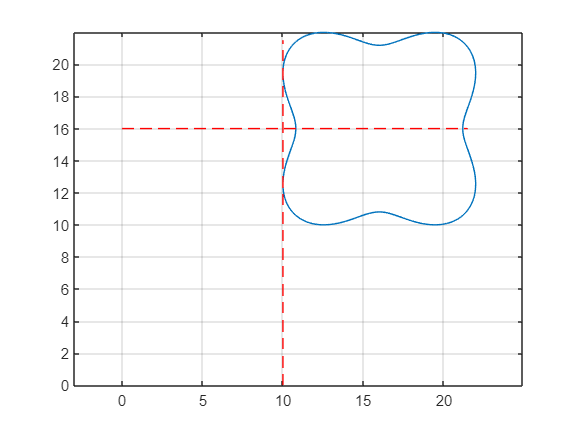

%¿Cuántos cm quiere desplazar el trébol desde su punta inferior?
trasl = 10;
[x, y] = cloverCartesian(x, y, trasl);

%Distancia total 
longitudTotal = sqrt((max(x)-min(x))^2+((max(y)-min(y))^2))...
                + sqrt(trasl^2*2);
%Información de los brazos
l1 = 24;
l2 = 8;
%Valores semilla
th1 = 120;       
th3 = -20;
%Matriz para almacenar los ángulos
theta = zeros(length(x), 3);
%Loop para calcular los ángulos
for i =1:length(x)
    thGuess = [th1; th3];
    [th1, th3, phi] = position(x(i),y(i),l1,l2,thGuess);
    theta(i,:) = [th1, th3, phi];
end

animation(theta(:,1:2), l1, l2, x, y)


No se pudo calcular la velcoidad angular de los eslabones usando NR, dado que se tienen 4 incógnitas y dos ecuaciones. Las incógnitas son $\dot \theta_1$, $\dot  \theta_3$, $\dot  \phi$ y $\dot  h$. ¿Qué se puede hacer en este caso? Aplicar diferencias finitias para calcular las derivadas de los ángulos. De esta manera se puede encontar las velocidad angulares y las aceleraciones angulares de cada uno de los eslabones. 

Se necesita conocer el $\Delta t$ requerido ¿Cómo calcularlo? Suponemos que la velocidad con que el mecanismo recorre la trayectoria es constante. Puede estar en 1 y 10 cm/s. Por tanto, tenemos que la distancia aproximada que debe recorrer es $4*(15 cm*escala)$

th1 = theta(:,1);
th3 = theta(:,2);
th2 = th3-th1;

velocidad = 2;
distanciaTotal = 4*(15*escala);
tiempoTotal = distanciaTotal/velocidad;

deltaT = tiempoTotal/(puntos-1);
w1 = zeros(puntos,1);
w2 = zeros(puntos,1);
w3 = zeros(puntos,1);
alfa1 = zeros(puntos,1);
alfa2 = zeros(puntos,1);
alfa3 = zeros(puntos,1);

[w1(:), alfa1(:)] = derivative(th1, deltaT);
[w2(:), alfa2(:)] = derivative(th2, deltaT);
[w3(:), alfa3(:)] = derivative(th3, deltaT);


%Propiedades eslabones
densidadPLA = 1.24/1000*100^3; %kg/m3
h = 2.5/100;        %alto
w = 2.5/100;        %profundidad
l1m = l1/100;
l2m = l2/100;
m1 = (h*w)*l1m*densidadPLA;
m2 = (h*w)*l2m*densidadPLA;
lc1 = l1m/2;
lc2 = l2m/2;
I1 = 1/12*(m1*(h^2+l1m^2));
I2 = 1/12*(m2*(h^2+l2m^2));
g = 9.81;

T = zeros(2,puntos);

for i =1:length(x)
    A = m1*lc1^2 + I1 + m2*l1m^2 + m2*lc2^2 + I2 + 2*m2*l1m*lc2*cosd(th2(i));
    B = m2*lc2^2 + I2 + m2*l1m*lc2*cosd(th2(i));
    D = 2*m2*l1m*lc2*sind(th2(i));
    E = 2*m2*l1m*lc2*sind(th2(i));
    U1 = g*(m1*lc1+m2*l1m)*cosd(th1(i)) + g*m2*lc2*cosd(th1(i)+th2(i));

    F = m2*lc2^2 + m2*l1m*lc2*cosd(th2(i)) + I2;
    H = m2*lc2^2 + I2;
    N = -m2*l1m*lc2*sind(th2(i));
    M = m2*l1m*lc2*sind(th2(i));
    U2 = g*m2*lc2*cosd(th1(i)+th2(i)); 

   T(:,i) = [A, B; F, H]*[alfa1(i); alfa2(i)] ...
       + [D*w1(i)*w2(i) + E*w2(i)^2; N*w1(i)*w2(i) + M*w1(i)*(w1(i)*w2(i))]...
       + [U1;U2];
end 

T1 = T(1,:)';
T2 = T(2,:)';
tiempo = [0:deltaT:tiempoTotal]';


%w1Max[rpm], T1rms[N.m], T1peak[N.m] 
[w1Max, T1rms, T1peak] = dimMotor(w1, T1, tiempoTotal, tiempo);
[w2Max, T2rms, T2peak] = dimMotor(w2, T2, tiempoTotal, tiempo);

motor1 = table(w1Max, T1rms, T1peak)
motor2 = table(w2Max, T2rms, T2peak)

subplot(2,2,1);
plot(tiempo, w1)
title("\omega_1 vs tiempo")
ylabel("\omega_1 [rad/s]")
xlabel("tiempo [s]")
grid on

subplot(2,2,2);
plot(tiempo, alfa1)
title("\alpha_1 vs tiempo")
ylabel("\alpha_1 [rad/s2]")
xlabel("tiempo [s]")
grid on

subplot(2,2,[3,4]);
plot(tiempo, T1)
title("T_1 vs tiempo")
ylabel("T_1 [N.m]")
xlabel("tiempo [s]")
grid on

%-----------------------------------------------------
subplot(2,2,1);
plot(tiempo, w2)
title("\omega_2 vs tiempo")
ylabel("\omega_2 [rad/s]")
xlabel("tiempo [s]")
grid on

subplot(2,2,2);
plot(tiempo, alfa2)
title("\alpha_2 vs tiempo")
ylabel("\alpha_2 [rad/s2]")
xlabel("tiempo [s]")
grid on

subplot(2,2,[3,4]);
plot(tiempo, T2)
title("T_2 vs tiempo")
ylabel("T_2 [N.m]")
xlabel("tiempo [s]")
grid on

function [x, y] = clover(phi, A, puntos)
    B = 5.5;
    theta = linspace(0,2*pi,puntos);
    theta = theta - 2.356;
    radio = (B + cos(4.*(theta-phi)))*7.5/(B+1)*A;
    polarplot(theta, radio);
    hold off

    x = radio.*cos(theta);
    y = radio.*sin(theta);
end

function [x, y] = cloverCartesian(x, y, trasl)
    maxX = max(x);
    maxY = max(y);

    x = x+maxX+trasl;
    y = y+maxY+trasl;

    horX = [0:0.5:maxX*2+trasl];
    horY = (maxY+trasl)*ones(length(horX));

    vertY = [0:0.5:maxY*2+trasl];
    vertX = trasl*ones(length(vertY));

    f1 = figure(1);
    plot(x, y);
    hold on;
    plot(horX, horY, "--r");
    plot(vertX,vertY, "--r");
    axis equal;
    grid on;
    hold off;

end

function [th1, th3, phi] = position(x,y,l1,l2, thGuess)

    error = 1e-5;
    NF = 1e-5*1000;
    th1 = thGuess(1);
    th3 = thGuess(2);
    h = sqrt(x^2+y^2);
    phi = atand(y/x);

    while error < abs(NF)
    
        F = [l1*cosd(th1) + l2*cosd(th3) - h*cosd(phi);
            l1*sind(th1) + l2*sind(th3) - h*sind(phi)];

        J = [-l1*sind(th1), -l2*sind(th3);
            l1*cosd(th1), l2*cosd(th3)];
        Dth = J\(-F);
        
        NF = norm(F);
        thGuess = Dth +thGuess;
        th1 = thGuess(1);
        th3 = thGuess(2);
    end

end


function animation(theta, l1, l2, x, y)
    %animacion = VideoWriter('animacion'); %open video file
    %animacion.FrameRate = 10;  %can adjust this, 5 - 10 works well for me
    %open(animacion)
    for i = 1:length(theta)
        %Posición de cada una de las juntas
        A = [0,0];
        B = [A(1) + l1*cosd(theta(i,1)), A(2) +...
            l1*sind(theta(i,1))];
        C = [B(1) + l2*cosd(theta(i,2)), B(2) +...
            l2*sind(theta(i,2))];
        
        xJunta = [A(1), B(1), C(1)];
        yJunta = [A(2), B(2), C(2)];
        
        f2 = figure(2);
        plot(x(1:i), y(1:i), "--g")
        hold on

        pl = line(xJunta, yJunta);
        pl.Color = 'blue';
        pl.LineStyle = '--';
        xlim([-10 25])
        ylim([0 30])
        grid on
        plot(x(i), y(i), "or")
        pause(0.05);

        %frame = getframe(gcf); %get frame
        %writeVideo(animacion, frame);
        clf

        if i == length(x)
            plot(x(1:i), y(1:i), "--g")
            hold on
    
            pl = line(xJunta, yJunta);
            pl.Color = 'blue';
            pl.LineStyle = '--';
            xlim([-10 25])
            ylim([0 30])
            grid on
            plot(x(i), y(i), "or")
            pause(0.05);
        end
    end
    %close(animacion)
end

function [omega, alfa] = derivative(theta, deltaT)
    A = zeros(length(theta), length(theta));

    %Primera fila
    A(1,1) = -3;
    A(1,2) = 4;
    A(1,3) = -1;
    
    %Valores intermedios
    for i=2:length(theta)-1
        A(i,i-1) = -1;
        A(i, i+1) = 1;
    end

    %última fila
    A(end,end) = 3;
    A(end, end-1) = -4;
    A(end, end-2) = 1;

    %Aplicamos coeficientes
    A = 1/(2*deltaT)*A;

    omega = A*theta;
    alfa = (A*A)*theta;
end

function [wMax, Trms, Tpeak] = dimMotor(w, T, tiempoTotal, tiempo)

    Trms = sqrt(1/tiempoTotal*trapz(tiempo, T.^2));
    wMax = max(abs(w))*60/(2*pi);
    Tpeak = max(abs(T));

end
